# **LiDAR SLAM**

clear all
close all
addpath('./functions');

## Tracciamento della traiettoria

### Definizione della scena 

sceneName = 'LargeParkingLot';
[sceneImage, sceneRef] = helperGetSceneImage(sceneName);

### Selezione manuale dei waypoints

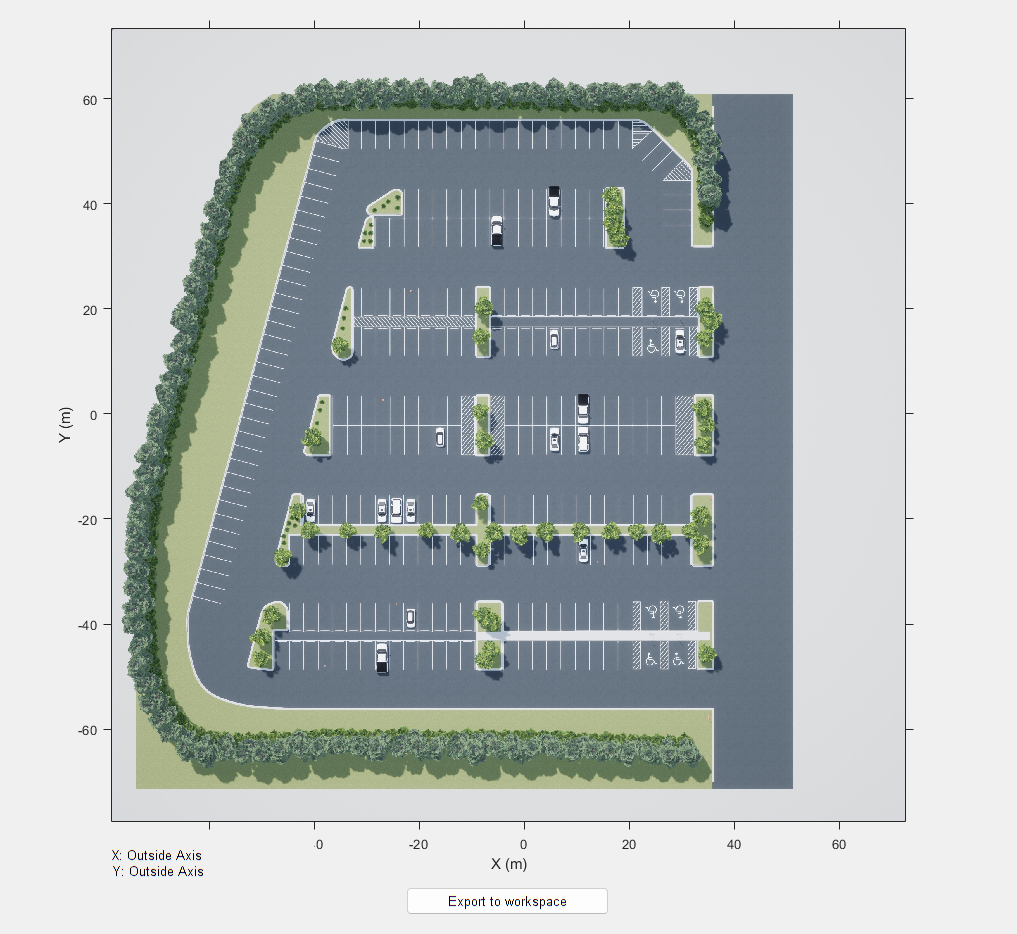

hFig = helperSelectSceneWaypoints(sceneImage, sceneRef);

fprintf('\n SCELTA DEI WAYPOINT DELLA TRAIETTORIA');


 SCELTA DEI WAYPOINT DELLA TRAIETTORIA

### Genera percorso continuo 

numPoses = size(refPoses{1}, 1);
refDirections  = ones(numPoses,1);   % Movimento in avanti
numSmoothPoses = 20 * numPoses;      % Aumenta la densità delle pose

[smoothRefPoses,~,cumLengths] = smoothPathSpline(refPoses{1}, refDirections, numSmoothPoses);

## Simulazione

modelName = 'CustomLidarSLAM';
open_system(modelName);
fprintf('\n SIMULAZIONE');


 SIMULAZIONE


% Parametri
simStopTime = 30;
set_param(modelName, 'StopTime', num2str(simStopTime));
timeVector = normalize(cumLengths, 'range', [0, simStopTime]);
set_param('CustomLidarSLAM/Simulation 3D Scene Configuration','SceneDesc', 'Large parking lot'); % da inserire manualmente

% Variabili per Simulink
refPosesX = [timeVector, smoothRefPoses(:,1)];
refPosesY = [timeVector, smoothRefPoses(:,2)];
refPosesT = [timeVector, smoothRefPoses(:,3)];

### Estrazione dei dati LIDAR

lidarData = out.lidarScans.signals.values;  
numScans = size(lidarData, 4); % Numero totale di scansioni nel tempo
ptCloudArr = helperPointClouds(out);

### Visualizzazione della scansione

fprintf('\n ESTRAZOINE DEI DATI LiDAR');


 ESTRAZOINE DEI DATI LiDAR

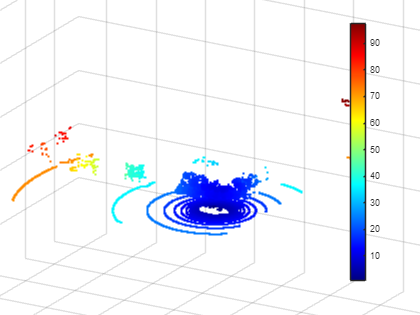


% Creazione della finestra di visualizzazione
figure;
hold on;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Nuvola di punti LIDAR in tempo reale');
axis equal;
grid on;
colormap jet; % Imposta la mappa di colori per la distanza
view(30, 20); % Imposta la vista isometrica
camzoom(2); % Aumenta il fattore per avvicinarti di più

lidarValues = squeeze(lidarData(:, :, :, 1)); % (32x360x3) -> (N x 3)
points3D = reshape(lidarValues, [], 3); % Trasforma in (32*360, 3)

% Calcola la distanza dall'origine per ogni punto
distances = sqrt(sum(points3D.^2, 2)); 

% Creazione dell'oggetto scatter per aggiornamenti in tempo reale
scatterHandle = scatter3(points3D(:, 1), points3D(:, 2), points3D(:, 3), 5, distances, 'filled');
colorbar; % Aggiunge una legenda per il colore basato sulla distanza

% Loop per aggiornare la visualizzazione senza errori
for scanIndex = 2:numScans  
    lidarValues = squeeze(lidarData(:, :, :, scanIndex)); % (32x360x3)  
    points3D = reshape(lidarValues, [], 3); % (32*360, 3)

    % Calcola la distanza dall'origine
    distances = sqrt(sum(points3D.^2, 2)); 

    % Aggiorna la nuvola di punti con colore basato sulla distanza
    set(scatterHandle, 'XData', points3D(:, 1), ...
                       'YData', points3D(:, 2), ...
                       'ZData', points3D(:, 3), ...
                       'CData', distances); % Colore basato sulla distanza
    drawnow;
end

## SLAM

### Prima trasformazione (tra la prima posa e la seconda)

ptCloud = ptCloudArr(1);
nextPtCloud = ptCloudArr(2);
gridStep = 0.5;
tform = pcregisterLOAM(ptCloud,nextPtCloud,gridStep);
disp(tform)

  rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-3.2400 5.3519 -0.3363]
                 R: [3×3 single]

                 A: [ 0.9885    0.1515   -0.0051   -3.2400
                     -0.1515    0.9879   -0.0322    5.3519
                      0.0002    0.0326    0.9995   -0.3363
                           0         0         0    1.0000]



### Filtraggio per tenere solo in punti in un intorno cilindrico

% Filtraggio cilindrico
egoRadius = 3.5;
cylinderRadius = 50;
selectedIdx = findPointsInCylinder(ptCloud,[egoRadius cylinderRadius]);
ptCloud = select(ptCloud,selectedIdx,OutputSize="full");
selectedIdx = findPointsInCylinder(nextPtCloud,[egoRadius cylinderRadius]);
nextPtCloud = select(nextPtCloud,selectedIdx,OutputSize="full");
fprintf('\n FILTRAGGIO CILINDRICO');


 FILTRAGGIO CILINDRICO

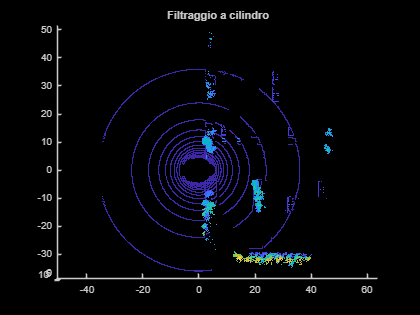


% Visualizzazione del filtraggio 
figure
hold on
title("Filtraggio a cilindro")
pcshow(ptCloud)
view(2)

### Ottimizzazione del parametro per l'estrattore di feature

minVal = 5;
maxVal = 20;
rmseValues = zeros(1, maxVal); % Preallocazione dell'array per RMSE
fprintf('\n OTTIMIZZAZIONE IPERPARAMETRO');


 OTTIMIZZAZIONE IPERPARAMETRO


for i = 1 : maxVal
    maxPlanarSurfacePoints = i;
    points = detectLOAMFeatures(ptCloud, MaxPlanarSurfacePoints=maxPlanarSurfacePoints);
    nextPoints = detectLOAMFeatures(nextPtCloud, MaxPlanarSurfacePoints=maxPlanarSurfacePoints);

    [~, rmseValue] = pcregisterloam(points, nextPoints);
    
    rmseValues(i) = rmseValue; % Salvo il valore di RMSE

    disp(['Valore maxPlanarSurfacePoints: ', num2str(i), ' RMSE ottenuto: ', num2str(rmseValue)])
end

Valore maxPlanarSurfacePoints: 1 RMSE ottenuto: 1.9773
Valore maxPlanarSurfacePoints: 2 RMSE ottenuto: 1.9014
Valore maxPlanarSurfacePoints: 3 RMSE ottenuto: 1.2035
Valore maxPlanarSurfacePoints: 4 RMSE ottenuto: 1.2082
Valore maxPlanarSurfacePoints: 5 RMSE ottenuto: 1.2766
Valore maxPlanarSurfacePoints: 6 RMSE ottenuto: 1.6563
Valore maxPlanarSurfacePoints: 7 RMSE ottenuto: 1.5576
Valore maxPlanarSurfacePoints: 8 RMSE ottenuto: 0.6601
Valore maxPlanarSurfacePoints: 9 RMSE ottenuto: 0.6516
Valore maxPlanarSurfacePoints: 10 RMSE ottenuto: 0.61874
Valore maxPlanarSurfacePoints: 11 RMSE ottenuto: 0.59512
Valore maxPlanarSurfacePoints: 12 RMSE ottenuto: 0.58895
Valore maxPlanarSurfacePoints: 13 RMSE ottenuto: 0.59232
Valore maxPlanarSurfacePoints: 14 RMSE ottenuto: 0.58492
Valore maxPlanarSurfacePoints: 15 RMSE ottenuto: 0.58482
Valore maxPlanarSurfacePoints: 16 RMSE ottenuto: 0.58097
Valore maxPlanarSurfacePoints: 17 RMSE ottenuto: 0.57864
Valore maxPlanarSurfacePoints: 18 RMSE ottenuto: 

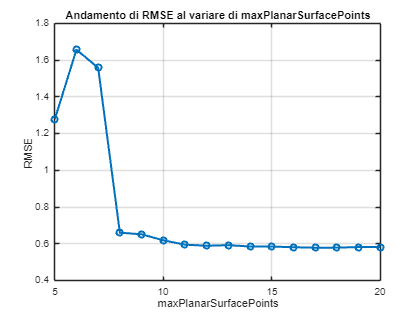


% Creazione del grafico
figure;
plot(minVal:maxVal, rmseValues(minVal:end), '-o', 'LineWidth', 2, 'MarkerSize', 6);
xlabel('maxPlanarSurfacePoints');
ylabel('RMSE');
title('Andamento di RMSE al variare di maxPlanarSurfacePoints');
grid on;


% Ricerca del valore migliore
[minRMSE, bestMaxPSP] = min(rmseValues);
disp(['Il valore minimo di RMSE è ', num2str(minRMSE), ' ed è prodoto da maxPlanarSurfacePoints = ' , num2str(bestMaxPSP)]);

Il valore minimo di RMSE è 0.57864 ed è prodoto da maxPlanarSurfacePoints = 17


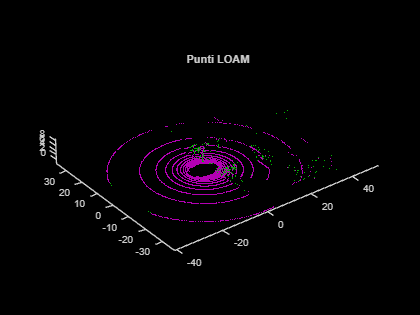


% Visualizzazione della mappa di punti LOAM
figure
hold on
title("Punti LOAM")
show(points,MarkerSize=12)

### Costruzione traiettoria senza mapping

% Ottenimento della posa iniziale
groundTruthPosesLidar = helperGetLidarGroundTruth(out);
absPose = groundTruthPosesLidar(1);

relPose = rigidtform3d;
vSetOdometry = pcviewset;

viewId = 1;
vSetOdometry = addView(vSetOdometry,viewId,absPose);
 
% Visualizzazione della scena con traiettoria ground truth
hScene = figure(Name=sceneName,NumberTitle="off");
helperShowSceneImage(sceneName);
hold on
plot(refPosesX(:,2),refPosesY(:,2),LineWidth=2)
xlim([-60 40])
ylim([10 60])
hScene.Position = [100 100 1000 500];

numSkip = 1;

% Stampa l'avanzamento
fprintf('\n FASE 1 LOAM');


 FASE 1 LOAM

disp(['Elaborata 1 posa su ',num2str(numel(ptCloudArr))]);

Elaborata 1 posa su 300


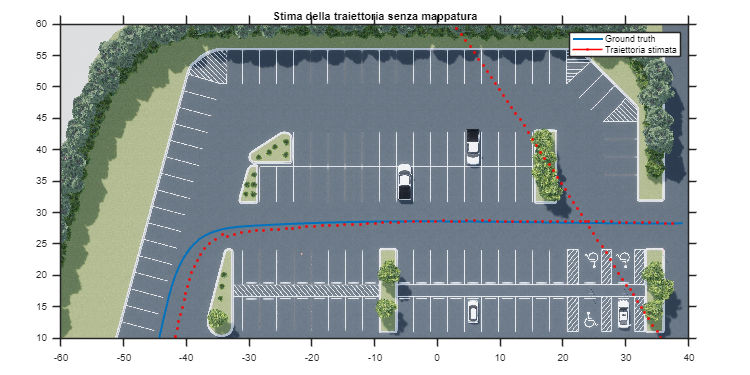

Elaborate 2 pose su 300
Elaborate 3 pose su 300
Elaborate 4 pose su 300
Elaborate 5 pose su 300
Elaborate 6 pose su 300
Elaborate 7 pose su 300
Elaborate 8 pose su 300
Elaborate 9 pose su 300
Elaborate 10 pose su 300
Elaborate 11 pose su 300
Elaborate 12 pose su 300
Elaborate 13 pose su 300
Elaborate 14 pose su 300
Elaborate 15 pose su 300
Elaborate 16 pose su 300
Elaborate 17 pose su 300
Elaborate 18 pose su 300
Elaborate 19 pose su 300
Elaborate 20 pose su 300
Elaborate 21 pose su 300
Elaborate 22 pose su 300
Elaborate 23 pose su 300
Elaborate 24 pose su 300
Elaborate 25 pose su 300
Elaborate 26 pose su 300
Elaborate 27 pose su 300
Elaborate 28 pose su 300
Elaborate 29 pose su 300
Elaborate 30 pose su 300
Elaborate 31 pose su 300
Elaborate 32 pose su 300
Elaborate 33 pose su 300
Elaborate 34 pose su 300
Elaborate 35 pose su 300
Elaborate 36 pose su 300
Elaborate 37 pose su 300
Elaborate 38 pose su 300
Elaborate 39 pose su 300
Elaborate 40 pose su 300
Elaborate 41 pose su 300
Elaborat


for k = (numSkip+1):numSkip:numel(ptCloudArr)
    prevPoints = points;
    viewId = viewId + 1;
    ptCloud = ptCloudArr(k);
    
    % Selezione del cilindro di punti 
    selectedIdx = findPointsInCylinder(ptCloud,[egoRadius cylinderRadius]);
    ptCloud = select(ptCloud,selectedIdx,OutputSize="full");

    % Feature extraction e downsampling
    points = detectLOAMFeatures(ptCloud,MaxPlanarSurfacePoints=bestMaxPSP);
    points = downsampleLessPlanar(points,gridStep);
    
    % Registrazione della posa relativa calcolata rispetto a quella precedente
    relPose = pcregisterloam(points,prevPoints,InitialTransform=relPose);

    % Calcolo e aggiunta della posa attuale alla traiettoria  
    absPose = rigidtform3d(absPose.A * relPose.A);
    vSetOdometry = addView(vSetOdometry,viewId,absPose);

    % Stampa l'avanzamento
    disp(['Elaborate ',num2str(k),' pose su ',num2str(numel(ptCloudArr))]);

    % Visualizzazione della triettoria stimata
    plot(absPose.Translation(1),absPose.Translation(2),Color="r",Marker=".",MarkerSize=8);
    xlim([-60 40])
    ylim([10 60])
    title("Stima della traiettoria senza mappatura")
    legend(["Ground truth","Traiettoria stimata"])
    pause(0.001)
    view(2)
end

### Costruzione traiettoria con mapping

% Ottenimento della posa iniziale
absPose = groundTruthPosesLidar(1);
relPose = rigidtform3d;

poses(150) = rigidtform3d;
vSetMapping = pcviewset;

ptCloud = ptCloudArr(1);
selectedIdx = findPointsInCylinder(ptCloud,[egoRadius cylinderRadius]);
ptCloud = select(ptCloud,selectedIdx,OutputSize="full");
points = detectLOAMFeatures(ptCloud,'MaxPlanarSurfacePoints',bestMaxPSP);
points = downsampleLessPlanar(points,gridStep);

% Creazione della mappa a partire dalla traiettoria precedentemente stimata
viewId = 1;
vSetMapping = addView(vSetMapping,viewId,absPose);

voxelSize = 0.1;
loamMap = pcmaploam(voxelSize);
addPoints(loamMap,points,absPose);

% Visualizzazione della scena con traiettoria ground truth
hScene = figure(Name=sceneName,NumberTitle="off");
helperShowSceneImage(sceneName);
hold on
plot(refPosesX(:,2),refPosesY(:,2),LineWidth=2)
xlim([-60 40])
ylim([10 60])
hScene.Position = [100 100 1000 500];

% Stampa l'avanzamento
fprintf('\n FASE 2 LOAM');


 FASE 2 LOAM

disp(['Elaborata 1 posa su ',num2str(numel(ptCloudArr))]);

Elaborata 1 posa su 300


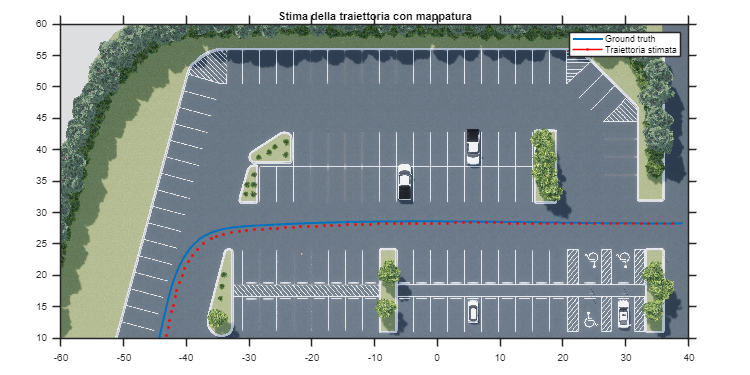

Elaborate 2 pose su 300
Elaborate 3 pose su 300
Elaborate 4 pose su 300
Elaborate 5 pose su 300
Elaborate 6 pose su 300
Elaborate 7 pose su 300
Elaborate 8 pose su 300
Elaborate 9 pose su 300
Elaborate 10 pose su 300
Elaborate 11 pose su 300
Elaborate 12 pose su 300
Elaborate 13 pose su 300
Elaborate 14 pose su 300
Elaborate 15 pose su 300
Elaborate 16 pose su 300
Elaborate 17 pose su 300
Elaborate 18 pose su 300
Elaborate 19 pose su 300
Elaborate 20 pose su 300
Elaborate 21 pose su 300
Elaborate 22 pose su 300
Elaborate 23 pose su 300
Elaborate 24 pose su 300
Elaborate 25 pose su 300
Elaborate 26 pose su 300
Elaborate 27 pose su 300
Elaborate 28 pose su 300
Elaborate 29 pose su 300
Elaborate 30 pose su 300
Elaborate 31 pose su 300
Elaborate 32 pose su 300
Elaborate 33 pose su 300
Elaborate 34 pose su 300
Elaborate 35 pose su 300
Elaborate 36 pose su 300
Elaborate 37 pose su 300
Elaborate 38 pose su 300
Elaborate 39 pose su 300
Elaborate 40 pose su 300
Elaborate 41 pose su 300
Elaborat


for k = (numSkip+1):numSkip:numel(ptCloudArr)
    prevPtCloud = ptCloud;
    prevPoints = points;
    viewId = viewId + 1;
    ptCloud = ptCloudArr(k);

    % Selezione del cilindro di punti 
    selectedIdx = findPointsInCylinder(ptCloud,[egoRadius cylinderRadius]);
    ptCloud = select(ptCloud,selectedIdx,OutputSize="full");

    % Feature extraction e downsampling
    points = detectLOAMFeatures(ptCloud,MaxPlanarSurfacePoints=bestMaxPSP);
    points = downsampleLessPlanar(points,gridStep);

    % Registrazione della posa relativa calcolata rispetto a quella precedente
    relPose = pcregisterloam(points,prevPoints,MatchingMethod="one-to-one",InitialTransform=relPose);

    % Ricerca della posa che permette l'allineamento dei punti alla mappa
    absPose = findPose(loamMap,points,relPose);
    poses(k) = absPose;

    % Aggiunta della posa alla traiettoria
    vSetMapping = addView(vSetMapping,viewId,absPose);
    addPoints(loamMap,points,absPose);

    % Stampa l'avanzamento
    disp(['Elaborate ',num2str(k),' pose su ',num2str(numel(ptCloudArr))]);

     % Visualizzazione della triettoria stimata
    plot(absPose.Translation(1),absPose.Translation(2),Color="r",Marker=".",MarkerSize=8)
    xlim([-60 40])
    ylim([10 60])
    title("Stima della traiettoria con mappatura")
    legend(["Ground truth","Traiettoria stimata"])
    pause(0.001)
    view(2)
end

## Valutazioni finali

### Visualizzazione delle differenze

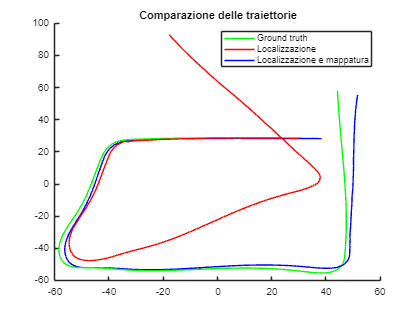

% Ottenimento della traiettoria di ground truth
groundTruthTrajectory = vertcat(groundTruthPosesLidar.Translation);

% Ottenimento delle traiettorie stimate
odometryPositions = vertcat(vSetOdometry.Views.AbsolutePose.Translation); % solo localizzazione
mappingPositions = vertcat(vSetMapping.Views.AbsolutePose.Translation); % mapping e localizzazione rielaborata

% Visualizzazione del confronto tra le traiettorie 
figure
hold on
plot3(groundTruthTrajectory(:,1),groundTruthTrajectory(:,2),groundTruthTrajectory(:,3),'g', LineWidth=1,DisplayName="Ground truth")
plot3(odometryPositions(:,1),odometryPositions(:,2),odometryPositions(:,3), 'r', LineWidth=1,DisplayName="Localizzazione")
plot3(mappingPositions(:,1),mappingPositions(:,2),mappingPositions(:,3),'b', LineWidth=1,DisplayName="Localizzazione e mappatura")
view(2)
legend
title("Comparazione delle traiettorie")

### Confronto delle traiettorie nella mapppa

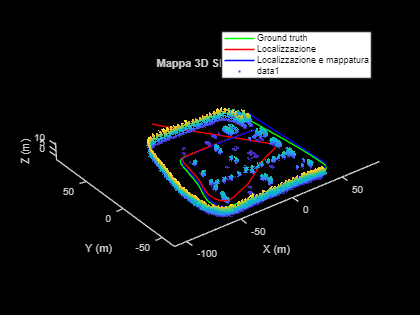

% Aggiunta della mappa al plot
mapPoints = loamMap.Points(loamMap.Points(:,3) >= 0.5, :); % cancella i punti relativi alla strada

pcshow(pointCloud(mapPoints));
title("Mappa 3D SLAM LiDAR");
grid off;
axis on;
xlabel("X (m)"); ylabel("Y (m)"); zlabel("Z (m)");
view(3);

### Confronto degli RMSE

% Calcolo dell'RMSE delle due traiettorie rispetto al ground truth
RMSEeval(groundTruthTrajectory,odometryPositions,mappingPositions);


 CONFRONTO DEGLI RMSE DELLE TRAIETTORIE
RMSE solo odometria: 37.5470 m
RMSE odometria e mappatura: 2.9080 m


## Eventuali sviluppi futuri (BETA)

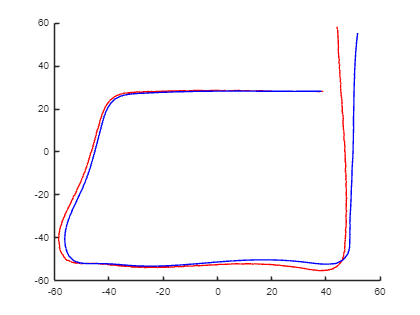

figure
hold on
imu = out.IMUsens.Data;
plot3(imu(:,1), imu(:,2), imu(:,3),'r') % traiettoria da IMU
plot3(mappingPositions(:,1),mappingPositions(:,2),mappingPositions(:,3),'b', LineWidth=1,DisplayName="Localizzazione e mappatura")

% Prealloca array di oggetti rigidtform3d
N = size(imu, 1);
tf_array(N) = rigidtform3d;  % inizializzazione array di oggetti

% Crea i rigidtform3d
for i = 1:N
    % Nessuna rotazione (identità)
    R = eye(3);

    % Traslazione
    t = imu(i, :);  % [x y z]

    % Crea la trasformazione
    tf_array(i) = rigidtform3d(R, t);
end


Frame 1 of 300
Frame 2 of 300
Frame 3 of 300
Frame 4 of 300
Frame 5 of 300
Frame 6 of 300
Frame 7 of 300
Frame 8 of 300
Frame 9 of 300
Frame 10 of 300
Frame 11 of 300
Frame 12 of 300
Frame 13 of 300
Frame 14 of 300
Frame 15 of 300
Frame 16 of 300
Frame 17 of 300
Frame 18 of 300
Frame 19 of 300
Frame 20 of 300
Frame 21 of 300
Frame 22 of 300
Frame 23 of 300
Frame 24 of 300
Frame 25 of 300
Frame 26 of 300
Frame 27 of 300
Frame 28 of 300
Frame 29 of 300
Frame 30 of 300
Frame 31 of 300
Frame 32 of 300
Frame 33 of 300
Frame 34 of 300
Frame 35 of 300
Frame 36 of 300
Frame 37 of 300
Frame 38 of 300
Frame 39 of 300
Frame 40 of 300
Frame 41 of 300
Frame 42 of 300
Frame 43 of 300
Frame 44 of 300
Frame 45 of 300
Frame 46 of 300
Frame 47 of 300
Frame 48 of 300
Frame 49 of 300
Frame 50 of 300
Frame 51 of 300
Frame 52 of 300
Frame 53 of 300
Frame 54 of 300
Frame 55 of 300
Frame 56 of 300
Frame 57 of 300
Frame 58 of 300
Frame 59 of 300
Frame 60 of 300
Frame 61 of 300
Frame 62 of 300
Frame 63 of 300
F

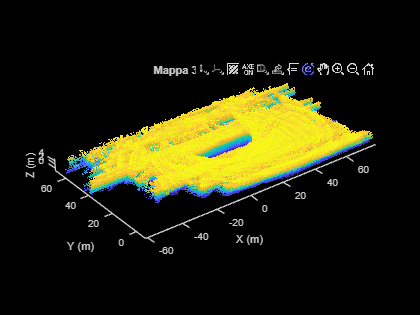

% Inizializzazione della mappa 3D
map3D = pointCloud(zeros(0,3));

% Numero di scansioni
numFrames = numel(ptCloudArr);

% Ciclo sulle scansioni e accumulo nella mappa
for frameIdx = 1:numFrames
    disp("Frame " + frameIdx + " of " + numFrames);
    
    % Estrai la scansione corrente e la posa associata
    ptCloud = ptCloudArr(frameIdx);
    ptCloudProcessed = helperPreprocessPC(ptCloud);
    
    t = imu(frameIdx, :);           % [x y z]
    R = eye(3);                     % nessuna rotazione
    pose = rigidtform3d(R, t);      % ora è un oggetto valido

    % Applica la trasformazione alla scansione
    transformedPtCloud = pctransform(ptCloudProcessed, pose);

    % Aggiungi la scansione trasformata alla mappa
    map3D = pcmerge(map3D, transformedPtCloud, 0.05); % Fusione con risoluzione 5 cm

    % Visualizza la mappa aggiornata
    clf; % Pulisce la figura per aggiornamenti fluidi
    pcshow(map3D);
    title("Mappa 3D SLAM LiDAR");
    grid off;
    axis on;
    xlabel("X (m)"); ylabel("Y (m)"); zlabel("Z (m)");
    view(3);
    drawnow;
end